clear all; close all; clc;
addpath("parareal_systems\")

Define function to be approximated

f = @(x) sin(10*x);

prepare training dataset

n_train = 50;
a_ = 0; b_ = 1;
x = sort(a_ + (b_ - a_).*rand(n_train, 1))';
y = f(x);

params

niter = 3e3;
shape = [1, 30, 30, 30, 30, 1];
sigma = @(t) tanh(t);
sigmaprime = @(t) 1 - tanh(t).^2;
eta = 0.005;

train

% disp('begin')
% tic
% [W_, b_] = TrainNetworkParareal( ...
%         x, y, niter, eta, sigma, sigmaprime, shape);
% toc
% disp('end')

result

% err = norm(y_ref(end,:) - y_par(end,:));
% disp(['error of parareal: ' num2str(err)])
% err = norm(y_ref(end,:) - y_seq(end,:));
% disp(['error of sequential: ' num2str(err)])
% disp(' ')
% disp(['time_ref: ' num2str(time_ref)])
% disp(['time_seq: ' num2str(time_seq)])
% disp(['time_par: ' num2str(time_par)])
load trained_regression_parareal.mat

display

n_test = 100;
x_test = linspace(0, 1, n_test);
y_test = f(x_test);

Let the test data flow throught the network to get the predictions

y_pred = PredictRegression(W_, b_, sigma, x_test);

### Plot results

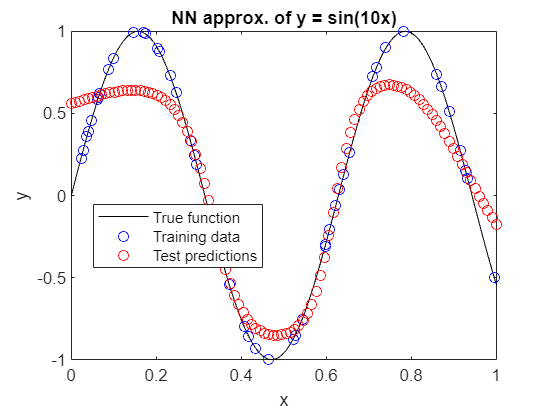

figure;
plot(x_test, y_test, 'k-');
hold on;
scatter(x, y, 'bo'); % Training data (blue dots)
scatter(x_test, y_pred, 'ro'); % Test predictions (red dots)
legend('True function', 'Training data', 'Test predictions', Location='best');
xlabel('x');
ylabel('y');
title('NN approx. of y = sin(10x)');